# Lab3: Comparison of exponential and running mean for random walk model 

Team1: Dmitry Shadrin and Eugenii Israelit, Skoltech, 08.04.2016 v1

## The objective of this laboratory work is to compare the errors of exponential and running  mean to choose the most effective quasi-optimal estimation method in conditions of uncertainty. 

## Additional important outcome of this exercise is the solution of identification problem of noise statistics that is crucial for reliable estimation.

Exponential Smoothing -

The weight of measurements decreases according to geometric progression or exponential law

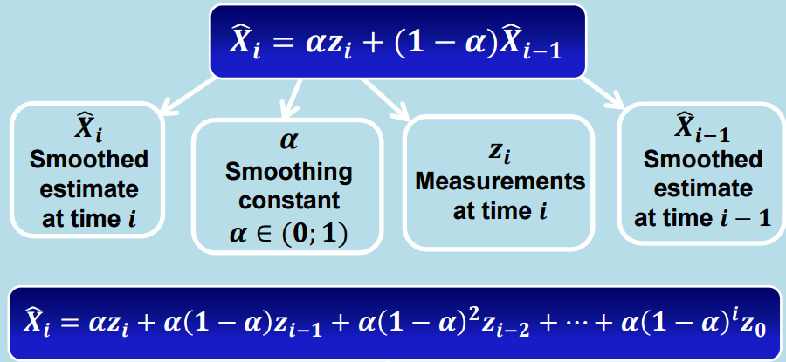

## 1)***Determination of optimal smoothing constant in exponential mean***

Let's Generate a true trajectory $X_i=X_{i-1}+W_i$  using the random walk model 

and Generate measurements  $Z_i$ of the process  $X_i$ , $Z_i=X_i+N_i$, 

where $N_i$ and $W_i$ –normally distributed random noise with zero mathematical expectation and variance  $σ_η^2$ $σ_w^2$.

clc; clear; close all;
addpath('../functions/');
set(gcf,'PaperPositionMode','auto');

n=100;
[X, Z, W, N] = randomWalk(n, 28, 97, 10);

Undefined function 'randomWalk' for input arguments of type 'double'.


Let's calculate noise statistics $σ_η^2$ and $σ_w^2$  and determine optimal smoothing coefficient $\alpha$ in exponential smoothing:

        $σ_{n}=E[v_i^2] - \frac{E[p_i^2] } 2$, $σ_{w}=E[p_i^2] - E[v_i^2] 
$ , $ χ=\frac{ σ_w^2  } { σ_η^2 }
$ ,  $α=\frac{-χ+ \sqrt{χ^2+4χ} } {2}$      

% alpha = calcAlpha(W, N);
alpha = 0.25;

Let's Determine the window size  m  (use round values) that provides equality of $σ_{RM}^2$ and $σ_{ES}^2$ using determined smoothing constant  $α$

$σ_{ES}^2=σ_{RM}^2$     =>    $m =   \frac {2-α} {α}$

m = (2-alpha)/alpha;
nearest_odd_m = 2*floor(m/2)+1;

Let's make running mean and exponential Smoothings and Plot the results :

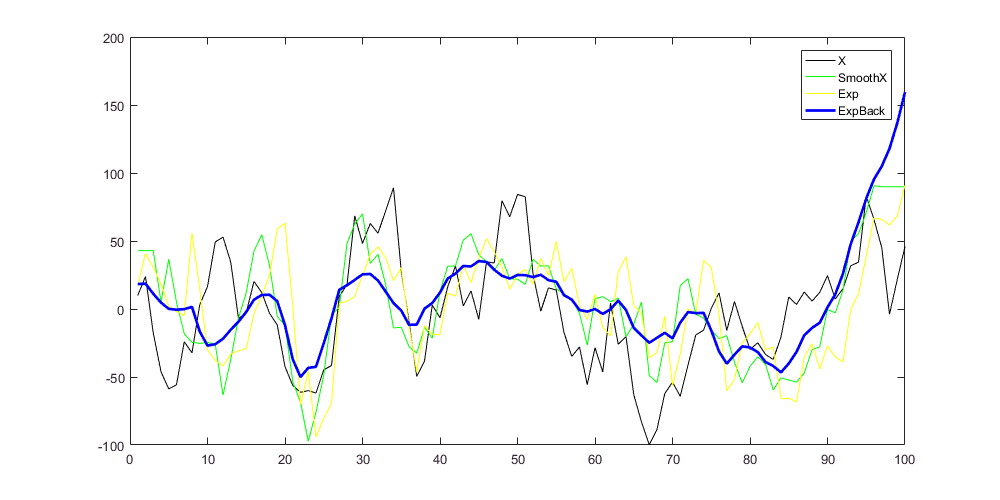

SmoothZ = smooth(Z, nearest_odd_m);
Exp = smoothExp(Z, alpha);
ExpBack = smoothExpBack(Z, alpha);

figure('position', [0, 0, 1000, 500]) ; 
plot(X,'black');
hold on;
plot(SmoothZ,'green');
plot(Exp,'yellow');
plot(ExpBack,'blue', 'LineWidth',2);
legend('X','SmoothX','Exp','ExpBack');